clear

syms f(x) g h
f(x) = x;
g = sym(0);
h = sym(0);
m = sym(0);
q = sym(0);
E = sym(1);
I = sym(1);

EX = computeExactSolution(E,I,f,g,h,m,q);

nELEM = 4;
eDegree = 2;
contVector = [-1 (eDegree-1)*ones(1,nELEM-1) -1];
FE = main(nELEM, eDegree, contVector, f, g, h, m, q,E*I);

K = FE.LinearSystem.K

$$K = \left(\begin{array}{cccc} 384 & -256 & 64 & 0\\ -256 & 384 & -320 & 128\\ 64 & -320 & 640 & -384\\ 0 & 128 & -384 & 256 \end{array}\right)$$

F = FE.LinearSystem.F

$$F = \left(\begin{array}{c} \frac{3}{32}\\ \frac{5}{32}\\ \frac{13}{96}\\ \frac{5}{64} \end{array}\right)$$

d = FE.LinearSystem.d

$$d = \left(\begin{array}{c} 0\\ 0\\ \frac{139}{8192}\\ \frac{1073}{24576}\\ \frac{913}{12288}\\ \frac{1105}{12288} \end{array}\right)$$

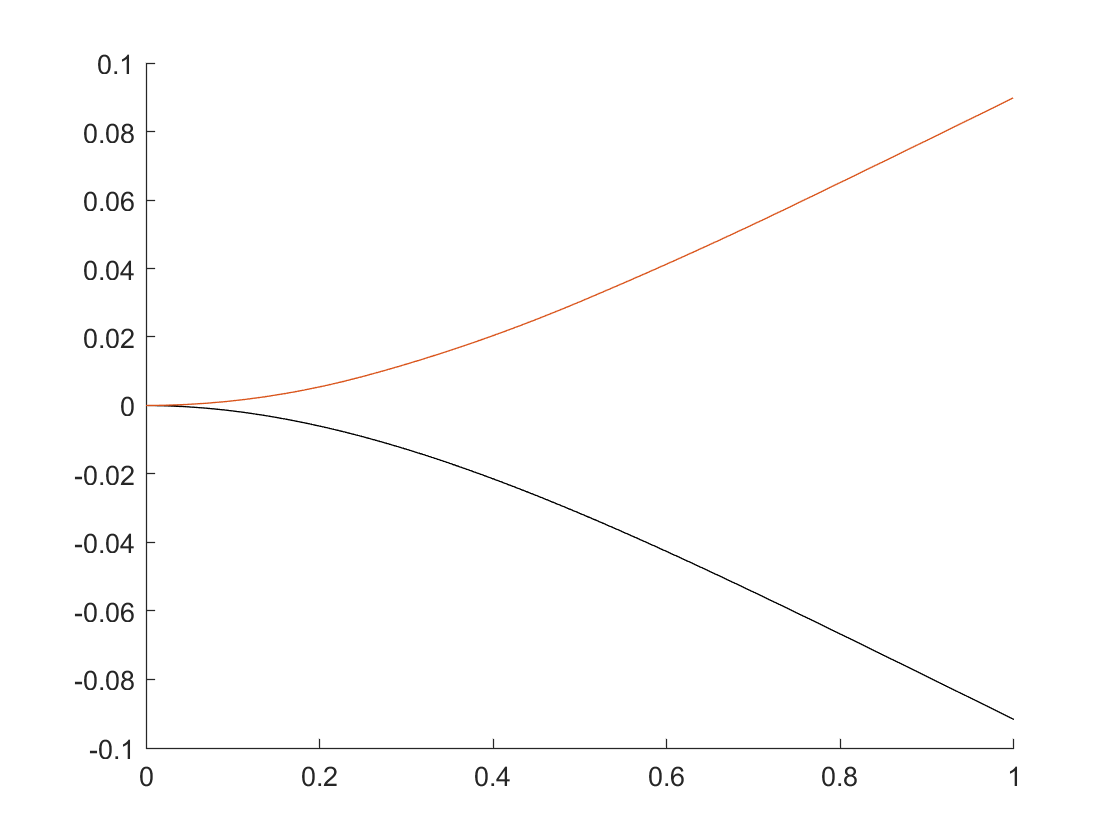


figure
hold on
fplot(EX.U,EX.domain,'k')
fplot(FE.U,EX.domain)

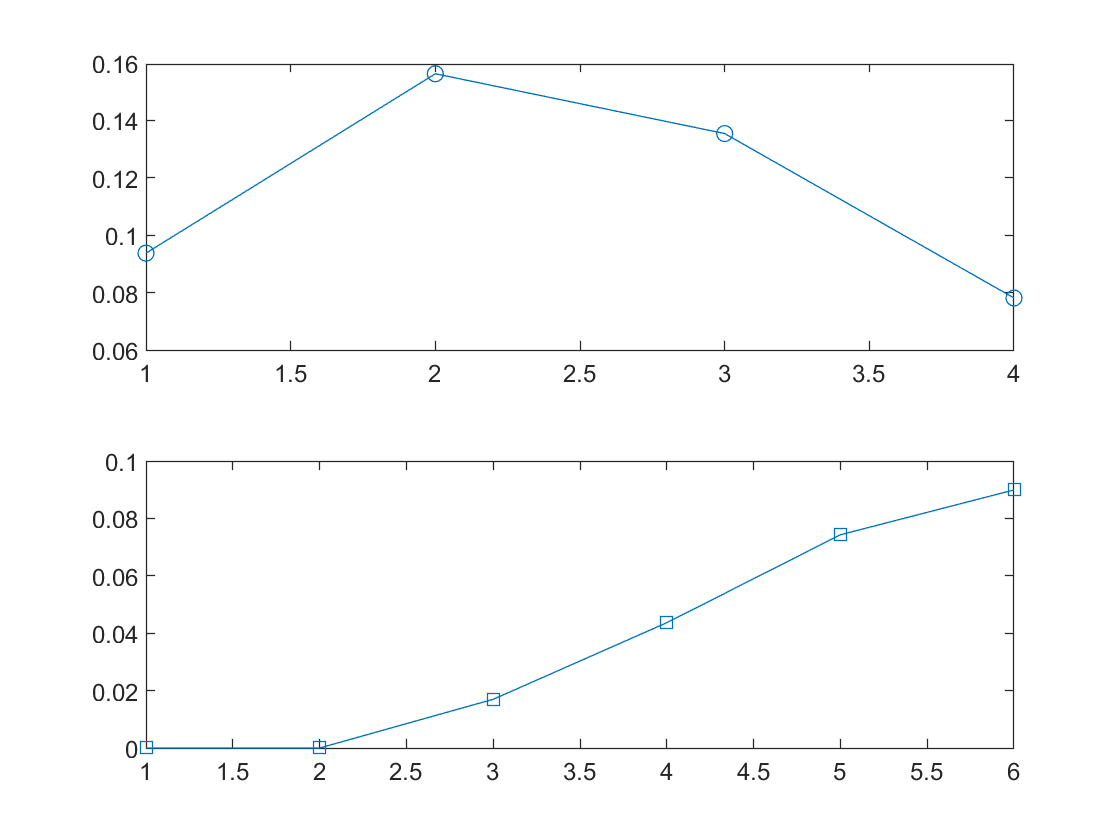


figure 
subplot(2,1,1)
plot(FE.LinearSystem.F,'-o')
subplot(2,1,2)
plot(FE.LinearSystem.d,'-s')


% figure
% fplot(FE.Elements.LBasisFuns,FE.Elements.LDomain)